## Midterm - Engs 105: Comp Methods for PDEs I

Author: Aaryan Agrawal

Date: 2/7/2024

Instructor: Prof. Paulsen

clear; close all

### Parameters

D = 0.5;
L = 10;
h = 0.01;
k = 0.0003;

tfinal = 50;

sigma = 0.1;
x0 = 5;

### Solution Mesh

x = [0:h:L];
t = [0:k:tfinal*k];

### Plot initial Conditions

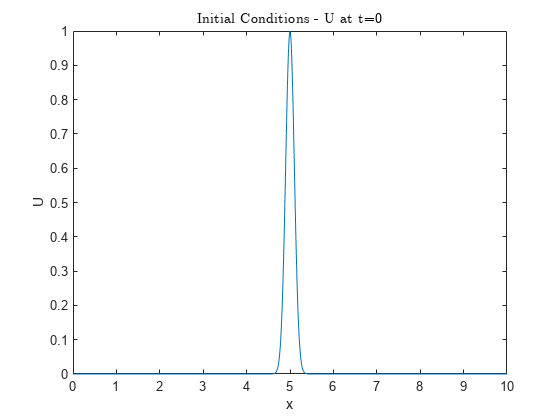

initial_cond = @(x) exp(-(x-x0).^2/(2*sigma*sigma));
plot(x, initial_cond(x))
ylabel("U")
xlabel('x')
title('Initial Conditions - U at t=0', 'Interpreter','latex')
exportgraphics(gcf, 'IC.png','Resolution',300)

## Finite Difference Numerical Solution

### FD Equation A

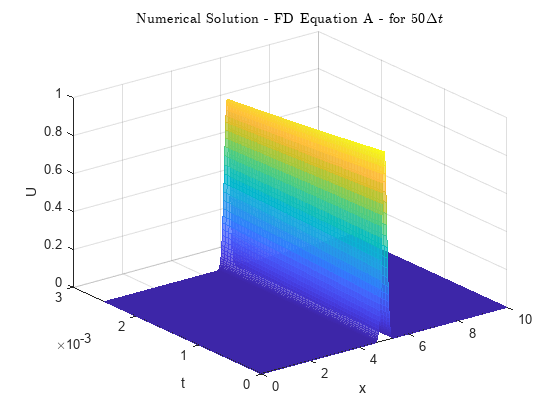

solutionA = readmatrix('solutionA.txt');
figure;
surf(x,t,solutionA, 'EdgeColor','flat', 'FaceAlpha',0.75);
ylabel('t')
xlabel('x')
zlabel('U')
title('Numerical Solution - FD Equation A - for $50 \Delta t$', 'Interpreter', 'latex');
exportgraphics(gcf, 'TransientA.png','Resolution',300)

### FD Equation B

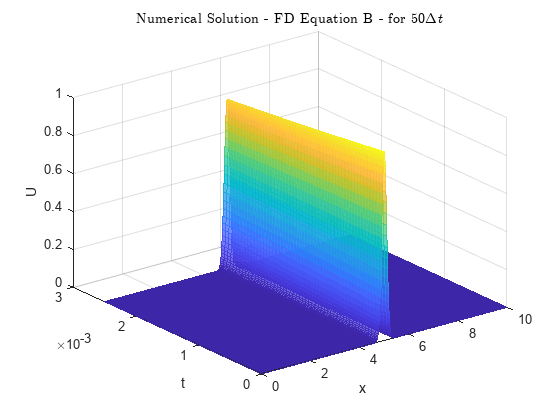

solutionB = readmatrix('solutionB.txt');
figure;
surf(x,t,solutionB, 'EdgeColor','flat', 'FaceAlpha',0.75);
ylabel('t')
xlabel('x')
zlabel('U')
title('Numerical Solution - FD Equation B - for $50 \Delta t$', 'Interpreter', 'latex');
exportgraphics(gcf, 'TransientB.png','Resolution',300)

## Stability & Accuracy

### A

rAcc = D*k/(h*h)

rAcc = 1.5000

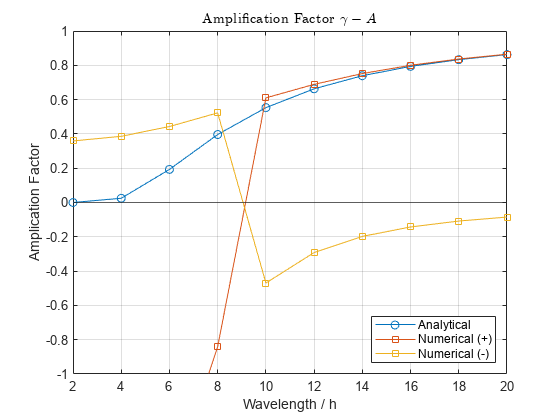


%Analytical Amplification Factor
analyticGamma_func = @(r, sigmah) exp(-r.*sigmah.*sigmah);
lambdaOverh = [2:2:20];
sigmah = 2*pi./lambdaOverh;
analyticGamma = analyticGamma_func(rAcc, sigmah);

%Numerical Analytical Factor for A
phi_func = @(sigmah) (2*cos(sigmah) - 2);
pA_func = @(sigmah) [1 -1-(3*rAcc/2)*(phi_func(sigmah)) (rAcc*phi_func(sigmah)/2)];
numericalGammaA = zeros([2, size(sigmah, 2)]);
for i = [1:size(sigmah, 2)]
    pA = pA_func(sigmah(i));
    numericalGammaA(:, i) = roots(pA);
end

figure
plot(lambdaOverh, analyticGamma, 'o-')
hold on
plot(lambdaOverh, numericalGammaA, 'square-')
yline(0)
ylim([-1 1])
yline(1)
yline(-1)
xticks(lambdaOverh)
xlim([2 20])
legend('Analytical', 'Numerical (+)', 'Numerical (-)', 'Location', 'southeast')
grid on
xlabel('Wavelength / h')
ylabel('Amplication Factor')
title('Amplification Factor $\gamma - A$', 'Interpreter', 'latex');
exportgraphics(gcf, 'AmplA.png','Resolution',300)

### B

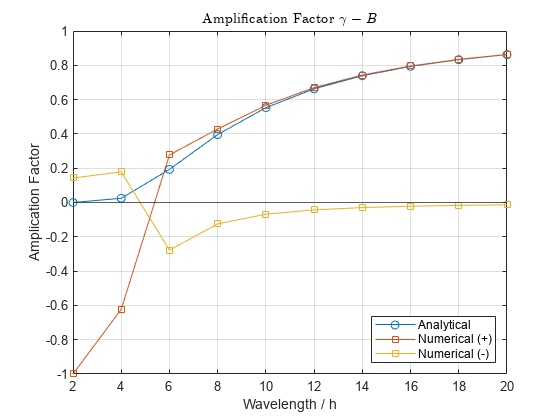

%Numerical Analytical Factor for B
pB_func = @(sigmah) [ 1-(5*rAcc/12)*(phi_func(sigmah)) -1-(8*rAcc/12)*(phi_func(sigmah)) phi_func(sigmah)*rAcc/12];
numericalGammaB = zeros([2, size(sigmah, 2)]);
for i = [1:size(sigmah, 2)]
    pB = pB_func(sigmah(i));
    numericalGammaB(:, i) = roots(pB);
end

figure
plot(lambdaOverh, analyticGamma, 'o-')
hold on
plot(lambdaOverh, numericalGammaB, 'square-')
yline(0)
yline(1)
yline(-1)
xticks(lambdaOverh)
xlim([2 20])
legend('Analytical', 'Numerical (+)', 'Numerical (-)', 'Location', 'southeast')
grid on
xlabel('Wavelength / h')
ylabel('Amplication Factor')
title('Amplification Factor $\gamma - B$', 'Interpreter', 'latex');
exportgraphics(gcf, 'AmplB.png','Resolution',300)

### Propagation Factor

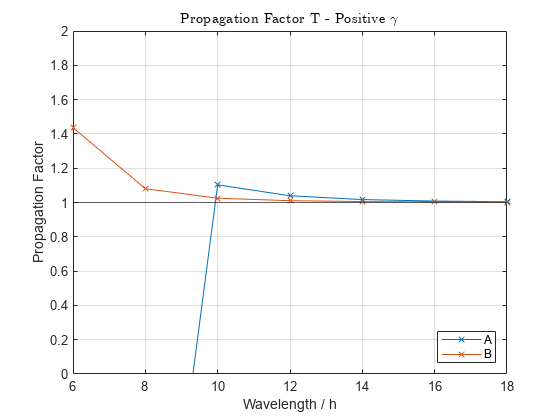

PropAPositive = numericalGammaA(1, :)./analyticGamma;
PropANegative = numericalGammaA(2, :)./analyticGamma;
PropBPositive = numericalGammaB(1, :)./analyticGamma;
PropBNegative = numericalGammaB(2, :)./analyticGamma;

PropPositive = [PropAPositive; PropBPositive];
PropNegative = [PropANegative; PropBNegative];

figure;
plot(lambdaOverh, PropPositive, 'x-');
xlim([6 18])
grid on
yline(1)
yline(0)
ylim([0 2])
xticks(lambdaOverh)
xlabel('Wavelength / h')
ylabel('Propagation Factor')
title('Propagation Factor T - Positive $\gamma$', 'Interpreter', 'latex');
legend('A', 'B', 'Location', 'southeast')
exportgraphics(gcf, 'PropPositive.png','Resolution',300)

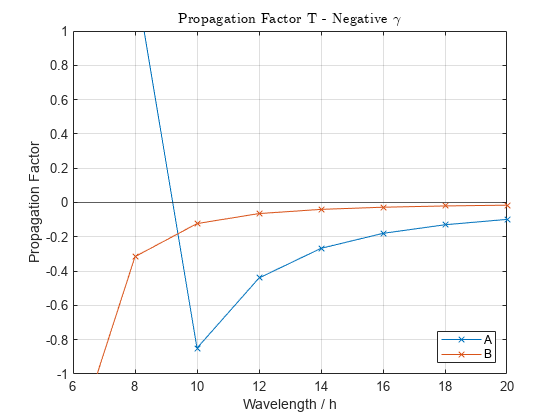


figure;
plot(lambdaOverh, PropNegative, 'x-');
xlim([6 20])
grid on
yline(1)
yline(0)
ylim([-1 1])
xticks(lambdaOverh)
xlabel('Wavelength / h')
ylabel('Propagation Factor')
title('Propagation Factor T - Negative $\gamma$', 'Interpreter', 'latex');
legend('A', 'B', 'Location', 'southeast')
exportgraphics(gcf, 'PropNegative.png','Resolution',300)

## Matlab Solution

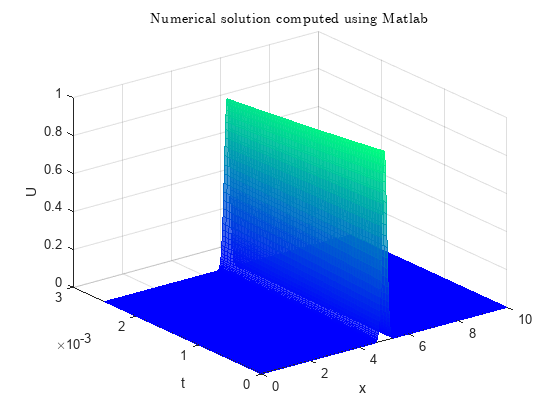

m = 0;
options = odeset('RelTol',1e-7,'AbsTol',1e-9);
mat_sol = pdepe(m,@pdex1pde,@pdex1ic,@pdex1bc,x,t,options);
mat_u = mat_sol(:,:,1);

figure;
surf(x,t,mat_u, 'EdgeColor','flat', 'FaceAlpha',0.75);
colormap(winter)
title('Numerical solution computed using Matlab', 'Interpreter','latex')
xlabel('x')
ylabel('t')
zlabel('U')
exportgraphics(gcf, 'TransientMatlab.png','Resolution',300)

### RMS Error w/ Numerical

% rmsA = rms(solutionA - mat_u, 2);
% rmsB = rms(solutionB- mat_u, 2);
% 
% figure;
% plot(t, rmsA, t, rmsB)

### Comparing behaviour

% N = size(solutionA, 2);
% 
% xRange = [4.9:0.05:5];
% xRangeIndex = int32(xToIndex([4.9:h:5], h));
% figure;
% plot(x(xRangeIndex), initial_cond(x(xRangeIndex)))
% hold on
% xline(xRange)
% 
% 
% for xQuery = xRange
%     figure
%     subplot(1, 2, 1)
%     index = int32(xToIndex(xQuery, h));
%     Axx = solutionA(:, index);
%     Bxx = solutionB(:, index);
%     Mxx = mat_u(:, index);
%     plot(t, Mxx-Bxx)
% 
%     subplot(1, 2, 2)
%     plot(t, Axx)
% end


Evolution of L-2 Norm Error

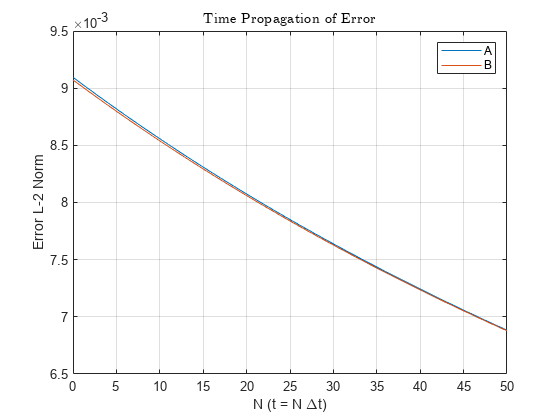

errorNormA = vecnorm(solutionA - mat_u, 2, 2);
errorNormB = vecnorm(solutionB - mat_u, 2, 2);
figure;
plot(t/k, errorNormA)
hold on
semilogy(t/k, errorNormB)
title('Time Propagation of Error', 'Interpreter','latex')
xlabel('N (t = N \Deltat)')
grid on
ylabel('Error L-2 Norm')
% legend('B')
legend('A', 'B')
exportgraphics(gcf, 'NormError.png','Resolution',300)

### Set up functions required to plot expected solution to problem using Matlab built-in PDE solvers

function [c, f, s] = pdex1pde(x,t,u,dudx)
D = 0.5;
c = 1;
f = D * dudx;
s = 0;
end

function u0 = pdex1ic(x)
sigma = 0.1;
x0 = 5;
u0 = exp(-(x - x0)^2/(2*sigma*sigma));
end

function [pl,ql,pr,qr] = pdex1bc(xl,ul,xr,ur,t)
pl = ul;
ql = 0;
pr = ur;
qr = 0;
end

### Other Utility Functions

function [index] = xToIndex(x,h)
    index = (x./h)+1;
end